data = load('gandalf_130618c3_24.mat');

% data = load('gandalf_130618c3_19.mat');
data.VSDdata(data.chamberpix==1 | data.bloodpix == 1,:) = 0;
start_frame = 55;
end_frame = 55;
res = it_offerElipse(mean(data.VSDdata(:,start_frame:start_frame,:),2)-1);
figure; mimg2(mean(data.VSDdata(:,start_frame:start_frame,:),2) - 1, 100, 100, -0.001, 0.0015, (start_frame:start_frame), [1 1 1], data.chamberpix, data.bloodpix);
h = image('CData', cat(3, zeros(size(res)), zeros(size(res)), zeros(size(res)))); set(h, 'AlphaData', 0.8 * res);
figure; imshow(res, 'InitialMagnification', 400);


% folder = 'C:\Users\itama\Desktop\eyePosToVSD\gandalf_toy_data\gandalf_130618c';
% files = dir(fullfile(folder,'*.mat'));  % adjust extension if needed
% fig1 = figure(1);
% fig2 = figure(2);
% % Loop over all files
% for k = 1:numel(files)
%     % Load data
%     filename = files(k).name;
%     filepath = fullfile(folder, filename);
%     data = load(filepath);
%     data.VSDdata(data.chamberpix==1 | data.bloodpix == 1,:) = 0;
%     start_frame = 55;
%     end_frame = 55;
%     res = it_offerElipse(mean(data.VSDdata(:,start_frame:start_frame,:),2)-1);
%     % update fig1
%     figure(fig1); 
%     clf; 
%     mimg2(...
%       mean(data.VSDdata(:,start_frame:start_frame,:),2) - 1, ...
%       100,100,-0.001,0.0015, ...
%       start_frame:start_frame, [1 1 1], data.chamberpix, data.bloodpix);
%     hold on;
%     h = image('CData', cat(3, zeros(size(res)), zeros(size(res)), zeros(size(res))));
%     set(h,'AlphaData',0.2*res);
%     axis image off;
%     title(filename,'Interpreter','none');
%     
%     % update fig2
%     figure(fig2);
%     clf;
%     imshow(res,'InitialMagnification',400);
%     axis image off;
%     title(filename,'Interpreter','none');
%     pause;
% 
% end

srcDir  = 'C:\Users\itama\Desktop\eyePosToVSD\gandalf_toy_data\gandalf_130618c';
dstDir  = 'C:\Users\itama\Desktop\eyePosToVSD\gandalf_toy_data\gandalf_130618c_ms_in_range';

% create destination if needed
if ~exist(dstDir,'dir')
    mkdir(dstDir);
end

% get all .mat files
files = dir(fullfile(srcDir,'*.mat'));

for k = 1:numel(files)
    srcFile = fullfile(srcDir, files(k).name);
    S = load(srcFile);
    
    % assume emEvent is a field in the loaded struct
    if isfield(S,'emEvents')
        ev = S.emEvents;
    else
        % in case it's nested, adjust this line to point at the correct struct
        fld = fieldnames(S);
        ev  = S.(fld{1}).emEvents;
    end

    if iscell(ev) && size(ev,1) > 1
        % first row is header, numeric data starts at row 2
        numEv = cell2mat(ev(2:end,:));
        offs  = numEv(:,2);
    elseif istable(ev)
        offs = ev.Offset;
    elseif isnumeric(ev)
        offs = ev(:,2);
    else
        warning('Unknown emEvent format in %s, skipping', files(k).name);
        continue;
    end

    % now test numeric offsets
    if any(offs >= 27 & offs <= 55)
        copyfile(srcFile, fullfile(dstDir, files(k).name));
    end
end

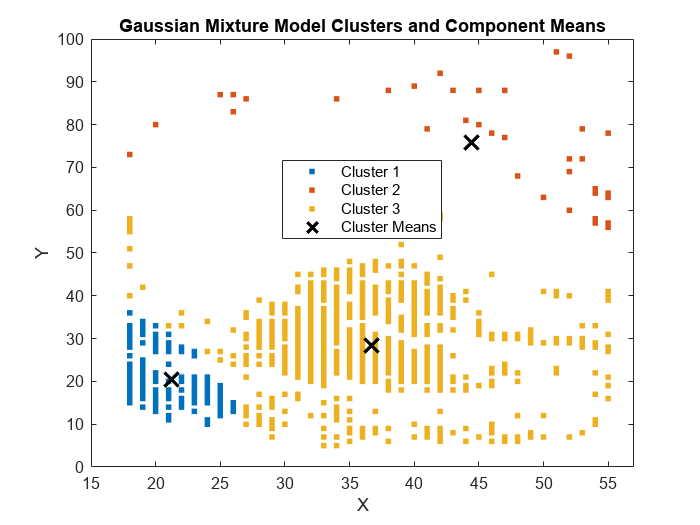

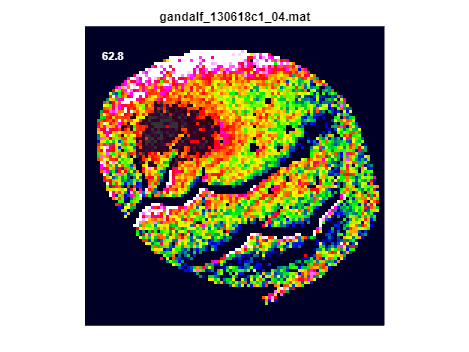

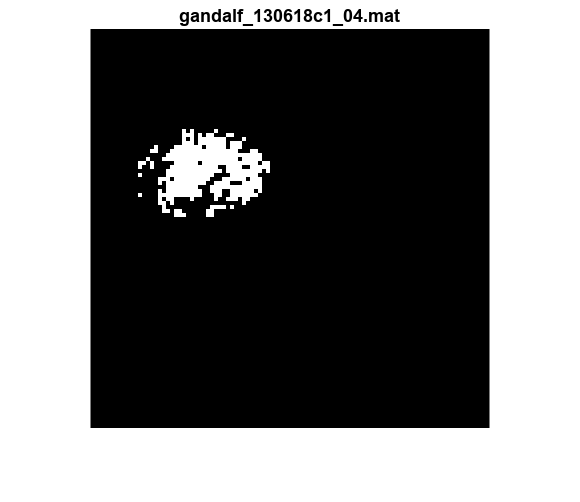

srcDir = 'C:\Users\itama\Desktop\eyePosToVSD\gandalf_toy_data\gandalf_130618c_ms_in_range';
files  = dir(fullfile(srcDir,'*.mat'));

for k = 1:numel(files)
    % Load
    filepath = fullfile(srcDir, files(k).name);
    S = load(filepath);
    
    % Extract emEvent (handle cell, table, or numeric)
    ev = S.emEvents;
    if iscell(ev)
        numEv = cell2mat(ev(2:end,:));
    elseif istable(ev)
        numEv = table2array(ev);
    else
        numEv = ev;
    end
    
    % get the offsets (2nd column)
    offs = numEv(:,2);
    
    % find first offset in [27,55]
    idx = find(offs>=27 & offs<=55,1);
    if isempty(idx)
        continue
    end
    
    % set frames
    start_frame = offs(idx) + 10;
    end_frame   = start_frame + 5;
    
    % prepare VSDdata
    data = S;  % assuming VSDdata, chamberpix, bloodpix live in S
    data.VSDdata(data.chamberpix==1 | data.bloodpix==1, :) = 0;
    
    % compute mask
    res = it_offerElipse( mean(data.VSDdata(:,start_frame:end_frame, :),2) - 1 );
    
    % plot 1: heatmap + overlay
    figure(1); clf;
    mimg2( mean(data.VSDdata(:,start_frame:end_frame, :),2) - 1, ...
           100,100, -0.001,0.0015, start_frame:end_frame, ...
           [1 1 1], data.chamberpix, data.bloodpix );
    hold on
    h = image('CData', cat(3,zeros(size(res)),zeros(size(res)),zeros(size(res))));
    set(h,'AlphaData',0.8*res);
    title(files(k).name,'Interpreter','none');
    axis image off
    
    % plot 2: binary mask
    figure(2); clf;
    imshow(res,'InitialMagnification',400); 
    title(files(k).name,'Interpreter','none');
    axis image off
    
    pause   % wait for keypress before next file
end